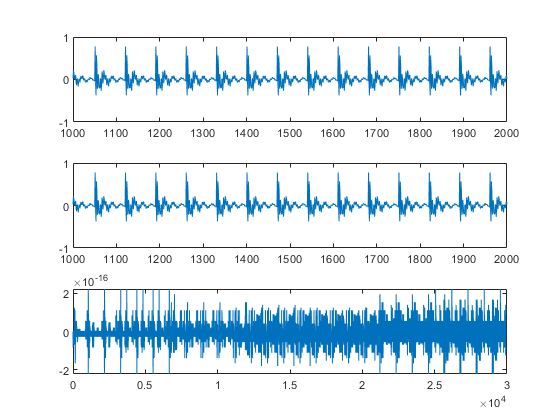

clear;
[x,fx]=audioread("test_period_70.wav");
[x2,fx2]=audioread("Afonso_8khz.wav");
[x3,fx3]=audioread("Gala_8khz.wav");

%Se debe acotar la duración de la señal a un múltiplo entero de 160

lx_ajustado=floor(length(x)/160);
x=x(1:lx_ajustado*160);

[xr,e,ak,bret,Nret]=RPE_LTP(x);

figure;
xaxis=1:length(x);
subplot(311); plot(xaxis(1000:2000),x(1000:2000));ylim([-1,1]);
subplot(312); plot(xaxis(1000:2000),xr(1000:2000));ylim([-1,1]);
subplot(313); plot(xaxis,x-xr);%ylim([-0.05,0.05]);

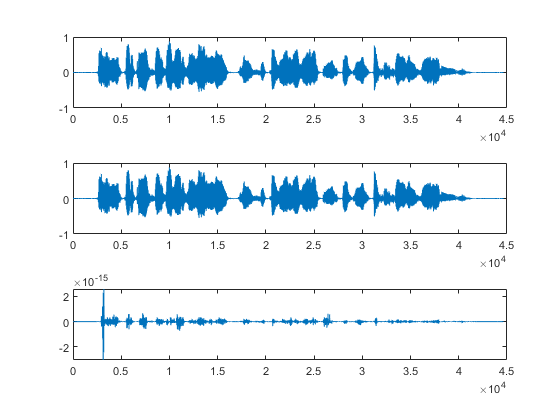


lx2_ajustado=floor(length(x2)/160);
x2=x2(1:lx2_ajustado*160);

[xr2,e2,ak2,bret2,Nret2]=RPE_LTP(x2);

figure;
xaxis2=1:length(x2);
subplot(311); plot(xaxis2,x2);ylim([-1,1]);
subplot(312); plot(xaxis2,xr2);ylim([-1,1]);
subplot(313); plot(xaxis2,x2-xr2);%ylim([-0.05,0.05]);

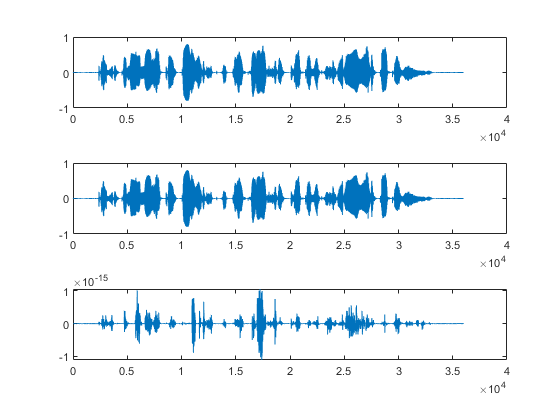






lx3_ajustado=floor(length(x3)/160);
x3=x3(1:lx3_ajustado*160);

[xr3,e3,ak3,bret3,Nret3]=RPE_LTP(x3);

figure;
xaxis3=1:length(x3);
subplot(311); plot(xaxis3,x3);ylim([-1,1]);
subplot(312); plot(xaxis3,xr3);ylim([-1,1]);
subplot(313); plot(xaxis3,x3-xr3);%ylim([-0.05,0.05]);

SNR

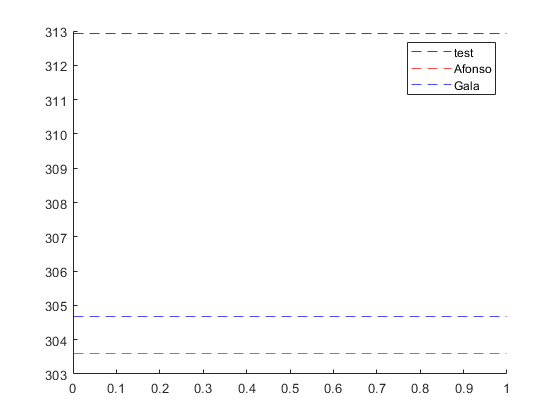

figure;
S=SNR(x,xr);
S2=SNR(x2,xr2);
S3=SNR(x3,xr3);
hold on
yline(S,'--k');
yline(S2,'--r');
yline(S3,'--b');
legend ('test','Afonso','Gala');
hold off